Definición de la señal de prueba $x(n)$


$$x(n)=[-1,1,-0.5,0.5]$$


La Tda Z de $x(n)$ viene dada por


$$X(z)=-1+z^{-1}-0.5z^{-2}+0.5z^{-3}$$


En matlab se representa mediante sus coeficientes

xz=[-1 1 -0.5 0.5]

xz =    -1.0000    1.0000   -0.5000    0.5000


Ecuación en diferencias del sistema 1


$$y(n)=x(n)-0.5x(n-1)+0.25x(n-2)$$


Función de transferencia del sistema 1


$$H(z)=1-0.5z^{-1}+0.25z^{-2}$$


hz=[1 -0.5 0.25]

hz =     1.0000   -0.5000    0.2500


Obtención de la respuesta del sistema mediante convolución. Compare con los resultados obtenidos en excel, deben ser iguales

yn1=conv(xz,hz)

yn1 =    -1.0000    1.5000   -1.2500    1.0000   -0.3750    0.1250


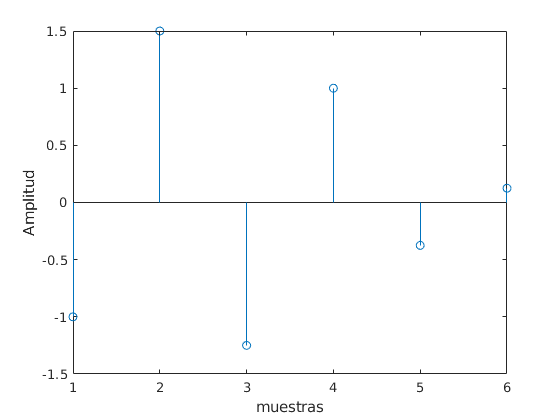

figure
stem(yn1)
xlabel('muestras')
ylabel('Amplitud')

Observe que se obtuvieron 6 valores, dicha longitud de $y(n)$ se obtiene mediente:

longitud xz + longitud hz -1

Para el caso del sistema 2 no se peude usar la convolución de forma directa. Observe su ecuación en diferencias


$$y(n)=0.5x(n)+0.1x(n-1)-0.1y(n-1)+0.2y(n-2)$$


y su función de transferencia


$$H(z)=\frac{0.5+0.1z^{-1}}{1+0.1z^{-1}-0.2z^{-2}}$$


Para obtener su respuesta ante la señal $x(n)$ se utiliza la función filter

yn2=filter([0.5 0.1],[1 0.1 -0.2],[xz zeros(1,10)])

yn2 =    -0.5000    0.4500   -0.2950    0.3195   -0.0409    0.0680   -0.0150    0.0151   -0.0045    0.0035   -0.0012    0.0008   -0.0003    0.0002


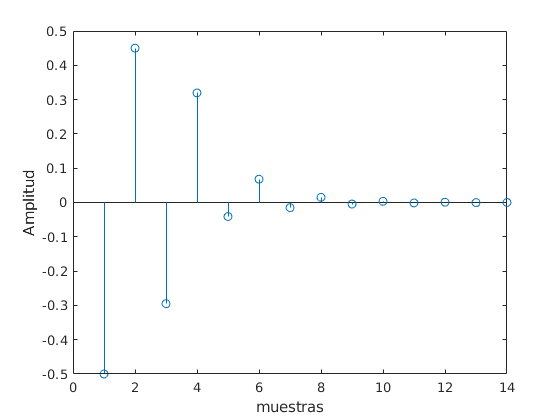

figure
stem(yn2)
xlabel('muestras')
ylabel('Amplitud')